# B1_Generate_Reference_Virtual_Patient.m

**Goal: **Prepare a parameter space that can be used to generate virtual patient populations.

**Workflow:**

- Create base parameter space (virtual population of 30,000 parameter sets; "`SSConfig-Analysis-Bast.mat`")

- Create specific Virtual Patient Population by resampling the base parameter space to match equilibrium behavior (CST stability pattern observed clinically; see below for more details)

- Create a list or probiotic strain characteristics to evaluate systematically according to a given virtual patient popuation

**Requirements:**

MATLAB Toolboxes: Parallel Computing, Bioinformatics, Symbolic Math

Custom Scripts: Add XYZ folders to your path

Kirschner Group Uncertainty and Sensitivity Analysis scripts: [http://malthus.micro.med.umich.edu/lab/usanalysis.html](http://malthus.micro.med.umich.edu/lab/usanalysis.html) [Current ODE LHS PRCC implementation (see README.txt in the downloaded ZIP file for instructions)](http://malthus.micro.med.umich.edu/lab/usadata/data/matlab-ode-lhs.04-24-2023.zip)

## 1. Generate Base Virtual Population (no Probiotic)

This code reads in an excel file that defines a parameter value distribution for each parameter in a model without probiotic.

The parameter distributions used are all log uniform to avoid negative parameter values for growth rates and positive values for self-interaction terms. *Future iterations may alter the parameter distributions (such as develop a pipeline to use log-normal distributions, which is common for physiological paramater values).*

For the model without probiotic, there are 12 parameters.

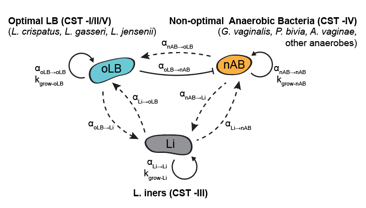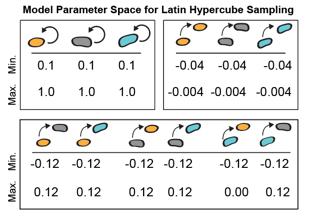

rng(1); % random seed
input_fdr = 'input_files/'; % location of the lhs excel file
flnm = strcat(input_fdr,'lhs_settings_input.xlsx'); % Excel file with necessary parameters
[params,~] = pull_LHS_parameters(flnm); % reads excel file and formats of Kirschner Group Uncertainty Analysis


NR = 30000; % Number of "samples/subjects"

paramMatrix = defineMatrix(params, NR,'parameter'); % Generates LHS parameter sets

analyze_Global_SS(paramMatrix,{'nAB','Li','oLB'}) % Call function that determines SS configurations

Set #250
Set #500
Set #750
Set #1000
Set #1250
Set #1500
Set #249
Set #248
Set #247
Set #246
Set #245
Set #244
Set #243
Set #499
Set #498
Set #497
Set #496
Set #495
Set #494
Set #493
Set #749
Set #748
Set #747
Set #746
Set #745
Set #744
Set #743
Set #999
Set #998
Set #997
Set #996
Set #995
Set #994
Set #993
Set #1249
Set #1248
Set #1247
Set #1246
Set #1245
Set #1244
Set #1243
Set #1499
Set #1498
Set #1497
Set #1496
Set #1495
Set #1494
Set #1493
Set #242
Set #241
Set #240
Set #239
Set #238
Set #237
Set #236
Set #492
Set #491
Set #490
Set #489
Set #488
Set #487
Set #486
Set #742
Set #741
Set #740
Set #739
Set #738
Set #737
Set #736
Set #992
Set #991
Set #990
Set #989
Set #988
Set #987
Set #986
Set #1242
Set #1241
Set #1240
Set #1239
Set #1238
Set #1237
Set #1236
Set #1492
Set #1491
Set #1490
Set #1489
Set #1488
Set #1487
Set #1486
Set #235
Set #234
Set #233
Set #232
Set #231
Set #230
Set #229
Set #485
Set #484
Set #483
Set #482
Set #481
Set #480
Set #479
Set #735
Set #734
Set #733
Set #7

Save workspace output as '`SSConfig-Analysis-Base.mat`' and move to the "`input_files/`" folder.

## 2. Define Population Equilibrium Behaviors (CST stability profile)

fdr_loc = "input_files/"; % location of output in section #1
load(strcat(fdr_loc,'SSConfig-Analysis-Base.mat'))

rng(2); % random seed
NumPats = 2000; % Total size of the simulated population

Define the Frequencies of Select Equilibrium Behaviors (**EB**). For testing on a BV+ population, the states can be assumed to have nAB dominance. Here, we matched the proportions observed in the HMP Cohort:

HMP Cohort: 60% 1SS nAB dominated, 31% 2SS nAB / Li dominated, 9% 2SS nAB / oLB dominated

Parameter sets were filtered for negative growth rates and positive self-interaction terms (values outside physiological ranges, which is important if the parameter distributions were generated using a normal distribution).

Parameter sets that had mixed microbial populations at steady-state were selected over those that were 100% dominated by one species.

Set #17
Set #34
Set #51
Set #68
Set #85
Set #102
Set #16
Set #15
Set #14
Set #13
Set #12
Set #11
Set #33
Set #32
Set #31
Set #30
Set #29
Set #28
Set #50
Set #49
Set #48
Set #47
Set #46
Set #45
Set #67
Set #66
Set #65
Set #64
Set #63
Set #62
Set #84
Set #83
Set #82
Set #81
Set #80
Set #79
Set #101
Set #100
Set #99
Set #98
Set #97
Set #96
Set #10
Set #9
Set #8
Set #7
Set #6
Set #5
Set #27
Set #26
Set #25
Set #24
Set #23
Set #22
Set #21
Set #20
Set #19
Set #18
Set #44
Set #43
Set #42
Set #41
Set #40
Set #39
Set #61
Set #60
Set #59
Set #58
Set #57
Set #56
Set #78
Set #77
Set #76
Set #75
Set #74
Set #73
Set #95
Set #94
Set #93
Set #92
Set #91
Set #90
Set #4
Set #3
Set #2
Set #1
Set #260
Set #259
Set #258
Set #257
Set #256
Set #255
Set #254
Set #418
Set #417
Set #416
Set #415
Set #414
Set #413
Set #412
Set #38
Set #37
Set #36
Set #35
Set #576
Set #575
Set #574
Set #573
Set #572
Set #571
Set #570
Set #55
Set #54
Set #53
Set #52
Set #72
Set #71
Set #70
Set #69
Set #892
Set #891
Set #890
Set #8

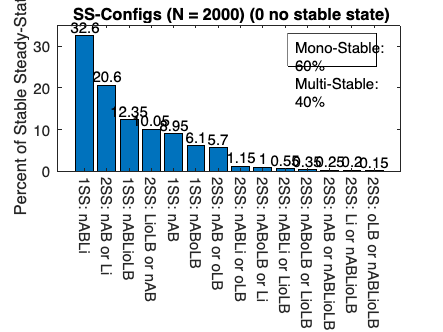

                                 Value    Count   Percent
                      1SS: [NO] CST-IV     1200     60.00%
      2SS: [NO] CST-IV or [Li] CST-III      620     31.00%
  2SS: [NO] CST-IV or [oLB] CST-I/II/V      180      9.00%


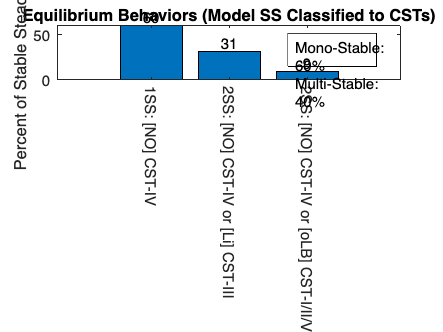

% ~~~~~~~~~~ EB Frequencies ~~~~~~~~~~ 
% Order: 1SS nAB, 1SS Li, 1SS oLB, 2SS Li or nAB, 2SS Li or oLB, 2SS oLB or nAB
hmp101 = [0.60 0.31 0.09]; % observed distribution

counts_per_EB = ceil(NumPats.*hmp101); % number of samples needed per EB
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

sel_cst_names = {'1SS: [NO] CST-IV';
    '2SS: [NO] CST-IV or [Li] CST-III';
    '2SS: [NO] CST-IV or [oLB] CST-I/II/V'};

sp_combos = [1 0 0; % indicates index of dominant species (nAB)
    1 1 0; % indicates index of dominant species (nAB or Li)
    1 0 1]; % indicates index of dominant species (nAB or oLB)

% Define Relative Abunance Range for Dominant Species
ub = 0.999; % upper bound
lb = 0.500; % lower bound

% Remove set with negative growth rates:
neg_gr = sum(LHSmat(:,1:3) < 0,2) > 0; % negative growth rate indexes
pos_si = sum(LHSmat(:,[4 8 12]) > 0,2) > 0; % positive self-interaction indexes

% Resample the base population for parameeter sets that meet critiera
s = RandStream('mlfg6331_64'); c = 1;
final_population = NaN(NumPats,length(param_names));
for EB_id = 1:length(sel_cst_names)

    % Finds index of EB subtype that meets non-negative growth rates &
    % non-positive self-interraction term
    indx = find(all_nm_CST == sel_cst_names{EB_id} & ~neg_gr & ~pos_si);

    % Checking Relative Abundance of Sample
    tmp = StbleSS(indx); % pulls analytitical steady-states (cell array: contains matrix within: rows = # steady-states, cols = species)
    abundance = cell2mat([tmp{:}]'); % converts cell aray to matrix
    rel_abundance = abundance ./ sum(abundance,2); % relative abundance
    dom_idx = find(sp_combos(EB_id,:)); % gets index for species that can be dominant in community
    spComp = NaN(size(tmp,1),length(dom_idx)); % collects information on species composition
    dom_array = repmat(dom_idx,size(tmp,1),1); % repeats dominant species index if there are multiple steady-states
    for i = 1:length(dom_idx)
        rtmp = rel_abundance(dom_array==dom_idx(i),dom_idx(i)); % gets relative abundance
        bid = rtmp > lb & rtmp < ub; % checks if it meets criteria for (+)-growth, (-)-self-interaction
        spComp(:,i) = bid; % saves the information
    end
    poss_indx = sum(spComp,2) == 1; % checks if criteria are met
    % End Checking Relative Abundance of Sample

    mix_idx = indx(poss_indx); % pull idxes of all sets that meet ub/lb
    leftover_indx = indx(~poss_indx); % idxes of sets that do not meet ub/lb
    
    num_samples = counts_per_EB(EB_id); % number of samples needed given input EB distribution
    leftover_num_samples = num_samples - length(mix_idx); % Determine number of samples needed to be selected that do not meet ub/lb
    
    if leftover_num_samples >= 0
        tmp_id = randsample(s,leftover_indx,leftover_num_samples); 
    else
        tmp_id = randsample(s,mix_idx,num_samples); % if number of ub/lb sets is greater than the number of sets needed, randomly select
        mix_idx = [];
    end

    final_population(c:c+num_samples-1,:) = LHSmat([mix_idx;tmp_id],:); % final virtual population
    c = c + num_samples;
end

% Check Distribution Matches Desired Output (Rename
% "SSConfig-Analysis-Virtual-Population.mat"
analyze_Global_SS(final_population,{'nAB','Li','oLB'}) % Call function that determines SS configurations

NOTE: Make sure to rename workspace once analysis is complete and move the file into the `input_files/ `folder.

Downstream code will asssum the names:

- `SSConfig-Analysis-HMP-Virtual-Population.mat`

- `SSConfig-Analysis-LV-Virtual-Population.mat`

## 3. Define Probiotic Strains

The result for this code will be used to determine characteristics of best probiotic candidates for different probiotic/antibiotic regimens. Note: nAB and NO may be used interchangably (both mean non-optimal anaerobic bacteria associated with BV).

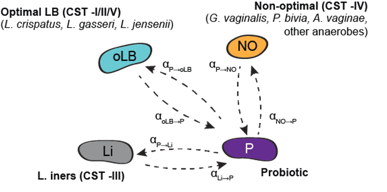

Parameter name by index: [4] kgrow-P [8] nAB->P [12] Li->P [16]  oLB->P [17] P->nAB [18] P->Li [19] P->oLB [20] P->P

rng(3);
input_fdr = 'input_files/'; % location of the excel file
flnm = strcat(input_fdr,'lhs_settings_input_probiotic.xlsx'); % Excel file with necessary parameters
[params,ICs] = pull_LHS_parameters(flnm); % reads excel file and formats for uncertainty analysis


NR = 500; % Number of "samples/strains"

pidx = [4,8,12,16,17,18,19,20]; % only pull the parameters associated with probiotic
paramMatrix = defineMatrix(params, NR,'parameter'); % runs LHS samplling as defined in the input excel file
newValueMat = paramMatrix(:,pidx); % pulls values only for probiotic parameters
newValueMat(:,end) = repmat(-0.022,NR,1); % sets probiotic self-interaction term to average value

strainListLHS = newValueMat; % systematic strain

Below is code to append the variable to the virtual population workspace. Make sure to double check the name of the workspace so that it matches the workspace name generated in #2.

save(strcat(input_fdr,'SSConfig-Analysis-HMP-Virtual-Population.mat'),'strainListLHS','-append')